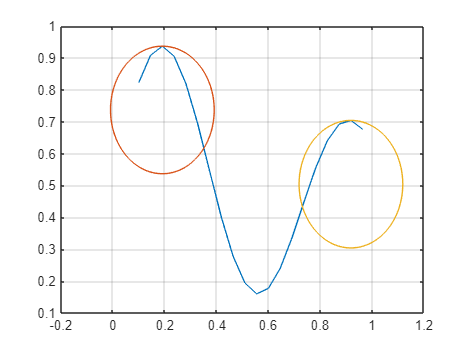



close all
clear all
clc

x = 0.1:1/22:1;
yTarget = ((1 + 0.6*sin(2*pi*x/0.7)) + 0.3*sin(2*pi*x))/2;
% potencialus centrai
[peaks, locs] = findpeaks(yTarget, x);

w0 = randn(1);
w1 = randn(1);
w2 = randn(1);

% centru ir spinduliu reiksmes
c1 = locs(1,1);
c2 = locs(1,2);
r1 = 0.2;
r2 = 0.2;
% pradinis grafikas
figure(1);
plot(x, yTarget);
hold on;


theta = linspace(0, 2*pi, 100); 
xR1 = c1 + r1 * cos(theta);
yR1 = (peaks(1) - r1) +  r1* sin(theta);
plot(xR1, yR1)

xR2 = c2 + r2 * cos(theta);
yR2 = (peaks(2) - r2) +  r2* sin(theta);
plot(xR2, yR2)
grid on
hold off

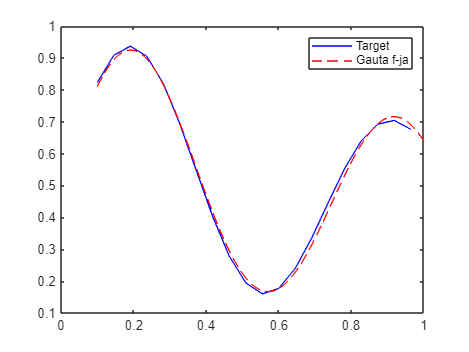


% mokymo zingsnis
step = 0.1;

for k=1:2500
    for n=1:length(x)
      F1=exp(-((x(n)-c1)^2)/(2*(r1^2)));
      F2=exp(-((x(n)-c2)^2)/(2*(r2^2)));

      yFunction(n) = F1*w1+F2*w2+w0;
      error = yTarget(n)-yFunction(n);

      w1 = w1 + step * error * F1;
      w2 = w2 + step * error * F2;
      w0 = w0 + step * error;
    end
end

% testavimas
x_test = linspace(0.1, 1, 200);
yTarget_Test = ((1 + 0.6*sin(2*pi*x_test/0.7)) + 0.3*sin(2*pi*x_test))/2;
for i = 1:length(x_test)
    F1=exp(-((x_test(i)-c1)^2)/(2*(r1^2)));
    F2=exp(-((x_test(i)-c2)^2)/(2*(r2^2)));
    y_test(i) = F1*w1+F2*w2+w0;
    offset(i) = y_test(i) - yTarget_Test(i);
end

figure(2)
plot(x, yTarget,"b", x_test,y_test, "r--")
legend('Target', 'Gauta f-ja')

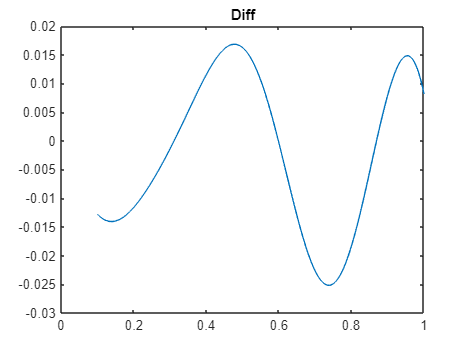


% skirtumas tarp "target" ir apskaiciuotos funkcijos
figure(3)
plot(x_test, offset)
title('Diff');